Jack Martin

Colorado School of Mines

SEED Lab

3/3/2024

velocity control system:

%% variables %%
velKp = 10; % proportial velocity2voltage gain

%% test %%
velocity;

Unrecognized function or variable 'velocity'.

voltage;

%% simulation %%
open_system('vctrlsystem') % open simulink system
out = sim('vctrlsystem') % run simulation

%% results %%
disp("//////// velocity control system ////////")
figure
%
plot(out.Voltage, 'linewidth', 2)
hold on
plot(time, actualvoltage, 'linewidth', 2)
xlabel('time (s)')
ylabel('voltage (V)')
hold off
%
plot(out.actualvelocity, 'linewidth', 2)
hold on
plot(out.desiredVelocity, 'linewidth', 2)
hold on
plot(time, velocity, 'linewidth', 2)
xlabel('time (s)')
ylabel('angular velocity (rad/s)')

angle and position control system:

% motor 0: left motor
% motor 1: rigth motor

%%%% variables %%%%
wheelCircum = 0.475722; % wheel circumference (feet)
rotationCircum = 1.14829; % robot rotation radius (feet)

K0 = 0.307 * 1600; % motor 0 DC gain (tps/V)
sig0 = 14; % motor 0 time constant reciprocal
K1 = 0.27 * 1600; % motor 1 DC gain (tps/V)
sig1 = 0.27 * 1600; % motor 1 time constant reciprocal

angKp = 4; % position proportional gain
angKi = 1; %* 1600 / 2 * pi; % position integral gain
posKp = 16; % position proportional gain
posKi = 8; %* 1600 / 2 * pi; % position integral gain
veldKp = 0.0008 % velocity difference proportional gain

veldKp = 8.0000e-04

velbKp = 0.0512 % velocity base proportional gain

velbKp = 0.0512


starttime = 0; % (s)
endtime = 20; % (s)
desiredAngle = timeseries([0, 90, 90, 90],[starttime, 0.1, 5, endtime]);
desiredPosition = timeseries([0, 0, 0, 0],[starttime, 4.9, 5, endtime]);

%%%% simulation %%%%
open_system('apctrlsystem.slx') % open simulink system
out=sim('apctrlsystem.slx') % run simulation

out =   Simulink.SimulationOutput:

     actualPositionBase: [1x1 timeseries] 
     actualPositionDiff: [1x1 timeseries] 
     actualVelcoityDiff: [1x1 timeseries] 
     actualVelocityBase: [1x1 timeseries] 
             simulation: [1x1 timeseries] 
                   tout: [469x1 double] 
            voltageBase: [1x1 timeseries] 
            voltageDiff: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


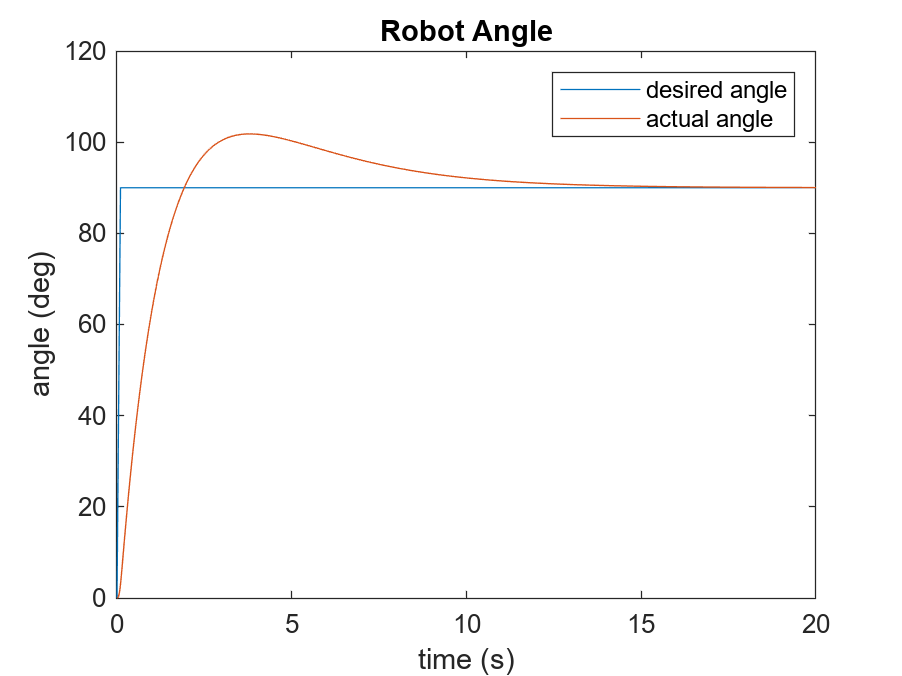


%%%% results %%%%
% angle:
clf
figure(1)
actualAngle = out.actualPositionDiff * (wheelCircum / 1600) * (360 / rotationCircum);
plot(desiredAngle)
hold on
plot(actualAngle)
hold off
legend('desired angle', 'actual angle')
xlabel('time (s)')
ylabel('angle (deg)')
title('Robot Angle')

% position:
figure(2)
actualPosition = out.actualPositionBase

  timeseries

  Common Properties:
            Name: 'actualPosition'
            Time: [469x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [469x1 double]
        DataInfo: 

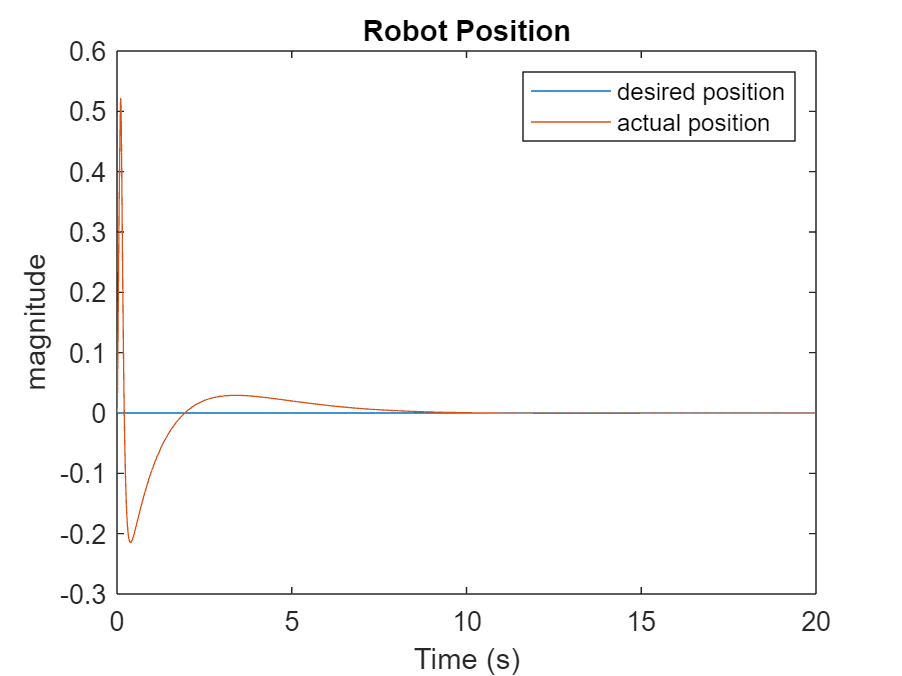

plot(desiredPosition)
hold on
plot(actualPosition)
hold off
legend('desired position', 'actual position')
xlabel('Time (s)')
ylabel('magnitude')
title('Robot Position')

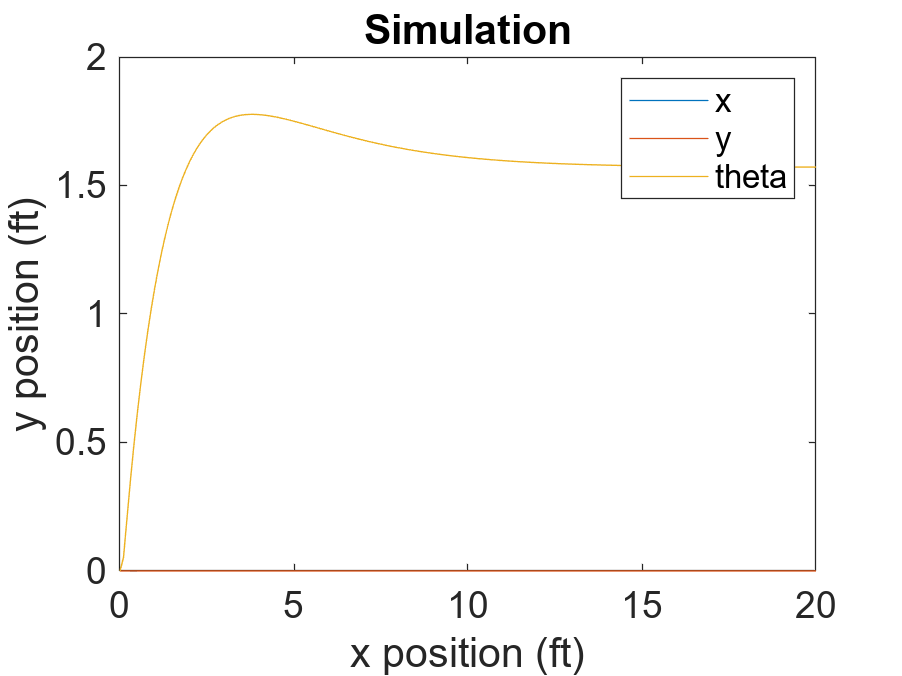

% simulation:
clf
figure(3)
plot(out.simulation)
set(gca,'fontsize',14)
xlabel('x position (ft)')
ylabel('y position (ft)')
legend('x','y','theta')
title('Simulation')

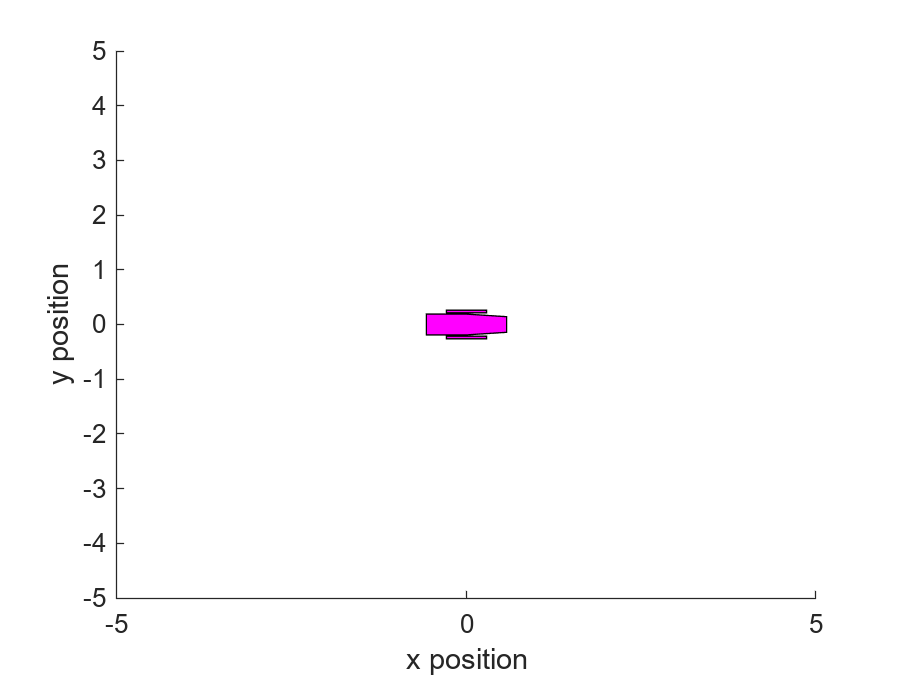

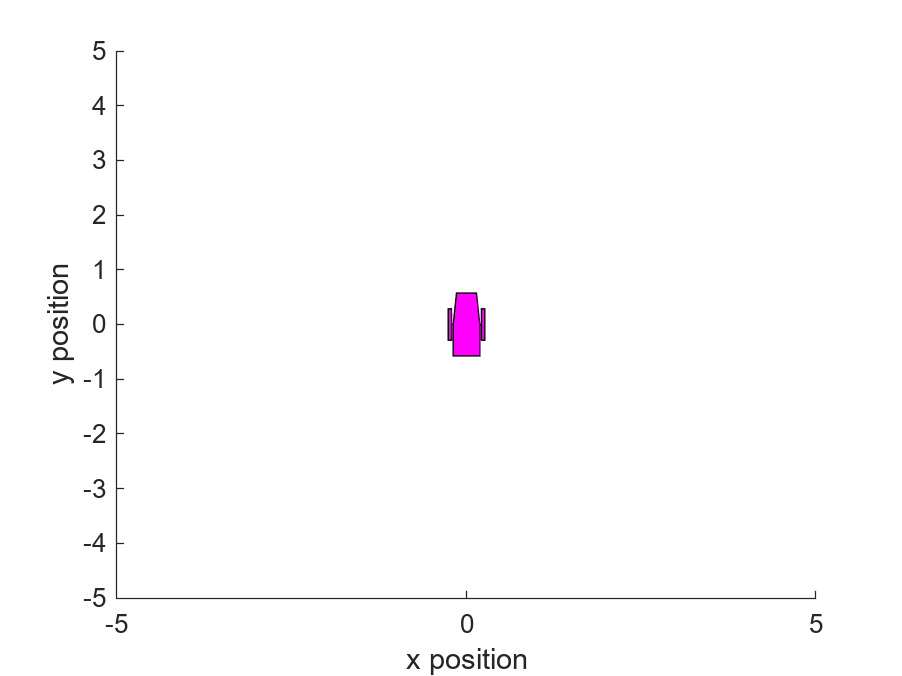

figure(4)
animate